# Estructuras de selección

A pesar de que la estructura de selección `if` es bastante útil, cuando se trabajen con matrices es preferible utilizar la función `find`. Para esta estructura se recomienda trabajar con escalares únicamente.

**Nota:** La familia de estructuras `if` son realmente útiles en funciones.

## Estructura` if` simple

Se empezará detallando la estructura con un ejemplo.

Supongamos que Alexandra quiere comprar un carro pero lo quiere de color azul. Entonces ella va a un concesionario. Si el concesionario tiene carros de color azul Alexandra comprará alguno. ¿Cómo se vería esto con la estructura `if`?

Pues bien,

clear

colorCar = 'b';         % b de blue (azul).

if colorCar == 'b'
    disp('Alexandra compra el carro.')
end

Al compilar el código anterior se notará que el mensaje `'Alexandra compra el carro.'` únicamente se despliega si el carro es de color azul (`colorCar = 'b'`). Pruebe a escribir otro color que no sea el azul y notará que no se desplegará nada debido a que la condición para que se imprima `'Alexandra compra el carro.'` es que el carro sea de color azul.

Básicamente esta es la idea principal de la estructura de selección `if`. El resto de estructuras que varían de esta (`else`, `elseif`) seguirán un concepto similar.

También se podría entender visualmente la estructura `if` simple mediante el siguiente diagrama de flujo:

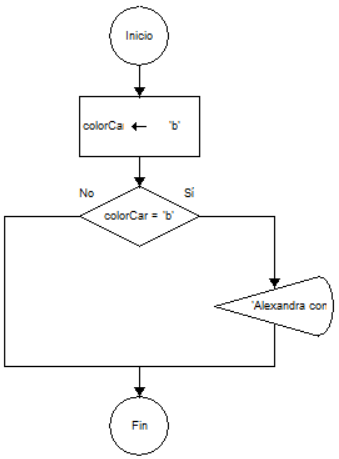

Así pues, la sintaxis de la estructura `if` es:

De ella podemos mencionar algunos detalles:

- La sitaxis se leería como: "Si la expresión se cumple realice estas instrucciones".

- La expresión (o expresiones) son comparaciones lógicas, así pues, si la comparación lógica es verdadera (`true`) ejecuta los comandos que le siguen, caso contrario no y básicamente "pasaría por alto" el `if` (como si no estuviera).

**Nota:** Recordar que el doble igual (`==`) nos sirve para comparar variables, es decir, es un operador lógico. Un igual (`=`) es para asignar variables. Los operadores lógicos se vieron en el **sc1to2**.

Además, como se mencionó en la introducción, esta estructura preferiblemente se utiliza con escalares más que con matrices. Veamos por qué.

clear

x1 = 7;         % Escalar.
x2 = 1:10;      % Matriz unidimensional.

if x1 < 10
    disp('Soy un escalar.')
end

if x2 < 10
    disp('Soy un vector.')
end

Aplicamos el mismo `if` al escalar `x1` y al vector (matriz unidimensional) `x2`. ¿Por qué sólo se desplegó `'Soy un escalar.'` y no `'Soy un vector.'`?

Claramente se observa que el escalar satisface la condición, por ende, se ejecuta el `disp`. Sin embargo, cuando pasamos el vector `x2` MATLAB hace un `all`. Es decir, si todos los elementos satisfacen la condición (función `all`) entonces ejecuta las líneas de código, caso contrario no. Como el vector `x2` contiene un 10, y 10 no es menor que 10 (es igual) entonces devuelve `false`, lo que provoca que no se ejecute el `disp`. Pruebe a escribir un vector o matriz con números menores que 10 para que vea que en ese caso sí se ejecutará el `disp`.

## Estructura` if`/`else`

Se se entendió la estructura `if` simple, esta estructura simplemente la complementa.

Retomando el caso de Alexandra pero complementándolo tenemos: si el concesionario tiene carros de color azul Alexandra compará uno, caso contrario no.

Veamos esto pero en código:

clear

colorCar = 'b';         % b de blue (azul).

if colorCar == 'b'
    disp('Alexandra compra el carro.')
else
    beep
    disp('Alexandra no compra el carro.')
end

Analicemos lo anterior:

- Si el carro es color azul (`colorCar = 'b'`) entonces se ejecutará el `disp` que indica que Alexandra compra el carro.

- Pero, si el carro no es de color azul, entonces se ejecuta el `disp` que indica que ella no compra el carro.

**Nota:** El comando `beep` es únicamente un sonido que indicará cuando se estén ejecutando dichas líneas de código.

La sintaxis de esta estructura es igual a la estructura del `if` simple, complemetando con el `else`.

Entonces, obtengamos algunas características de esta estructura:

- La sixtasis se leería como: "Si la expresión se cumple realice estas instrucciones (`statements1`), caso contrario, realice estas instrucciones (`statements2`) ".

- Las expresiones siguen siendo comparaciones lógicas.

- En este caso si o si se ejecutarán ciertas instrucciones: las correspondientes a que se cumpla la condición o no.

**Nota:** Para esta estructura se hacen las mismas consideraciones en cuanto a las variables a comparar que en la estructura `if` simple.

Complementando el diagrama de flujo para el `if` simple tenemos:

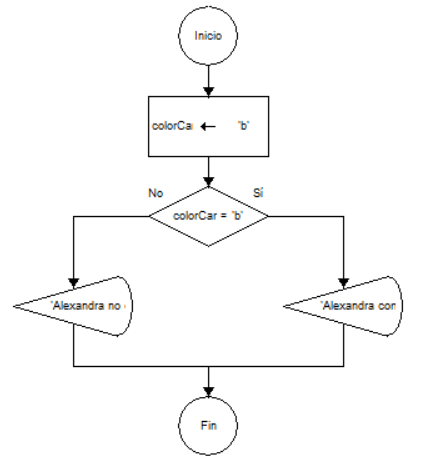

## Estructura` elseif`

Se se entendió la estructura `if` simple e `if`/`else`, esta estructura es la completa de las anteriores.

Retomando el caso de Alexandra pero ahora añadiendo unos detalles tenemos: si el concesionario tiene carros de color azul Alexandra compará uno, caso contrario no. Si el concesionario tiene carros de color rojo también lo compraría.

Veamos esto pero en código:

clear

colorCar = 'b';         % b de blue (azul), r de red (rojo).

if colorCar == 'b'
    disp('Alexandra compra el carro.')
elseif colorCar == 'r'
    disp('Alexandra compra el carro.')
else
    beep
    disp('Alexandra no compra el carro.')
end

Analicemos lo anterior:

- Si el carro es color azul (`colorCar = 'b'`) entonces se ejecutará el `disp` que indica que Alexandra compra el carro.

- O si no, si el carro es color rojo (`colorCar = 'r'`) entonces se ejecutará el `disp` que indica que Alexandra compra el carro.

- Pero, si el carro no es de color azul ni rojo, entonces se ejecuta el `disp` que indica que ella no compra el carro.

Por supuesto que también pudo ser pobile utilizar el siguiente código:

clear

colorCar = 'b';         % b de blue (azul), r de red (rojo).

if colorCar == 'b' || colorCar == 'r'
    disp('Alexandra compra el carro.')
else
    beep
    disp('Alexandra no compra el carro.')
end

Sin embargo, se hizo de la primera forma para mostrar que si se tienen varias condiciones es posible anidarlas (ponerlas una detrás de otra). Pero como se ve, hay otras formas de hacer lo mismo optimizando el código.

**Nota:** No se muestra el diagrama de flujo debido a que el programa libre utilizado para hacer estos diagramas (DFD) no dispone de una forma simple y entendible para mostrar los `if`/`else`/`elseif`. Sin embargo, si se quiere ver un diagrama de este tipo, revisar la página 255 y 256 del libro guía.

La sintaxis de esta estructura es la completa del `if`.

Entonces, obtengamos algunas características de esta estructura:

- La sixtasis se leería como: "Si la expresión se cumple realice estas instrucciones (`statements1`), o si se cumple esta expresión realice estas instrucciones (`statements2`), caso contrario, realice estas instrucciones (`statements3`) ".

- Las expresiones siguen siendo comparaciones lógicas.

- En este caso si o si se ejecutarán ciertas instrucciones: las correspondientes a la expresión verdadera.

Hay un detalle que no se mencionó antes debido a que todavía no se mostraba la estructura completa del `if`: una vez que se satisface una expresión, únicamente se compilarán las instrucciones dentro de esa expresión y el resto ya no, así falten expresiones por verificarse.

Veamos un ejemplo: dado un número, indicar si es positivo, negativo o cero.

clear

n = randi([-10 10]);        % Número entero aleatorio entre -10 y 10.

if n > 0
    disp('Positivo.')
elseif n < 0
    disp('Negativo.')
else
    disp('Cero.')
end

Entonces, suponiendo que `n = 5`, MATLAB entrará dentro del primer `if` y realizará la comparación: `5 > 0`. Como esto es verdadero, realizará las instrucciones dentro de esta expresión verdadera (desplegar `Positivo.`) y ya no ejecutará el resto de `if`'s.

Si `n = -3` llegaría hasta el segundo `if`, y si `n = 0` pasaría por cada `if` hasta el final (únicamente porque la verificación de que `n` sea cero está al final).

## Estructura `switch` y `case`

La estructura `switch`/`case` básicamente es un `if` más entendible. 

De hecho, cualquier cosa que pueda hacer con `switch`/`case `se podría hacer con `if`/`else`/`elseif`. Sin embargo, el código es un poco más fácil de leer con `switch`/`case`, una estructura que le permite elegir entre múltiples salidas, con base en ciertos criterios. Ésta es una importante distinción entre  `switch`/`case` y `elseif`.

Los criterios pueden ser un escalar o una cadena. En la práctica se usa más con cadenas que con escalares.  

Su sintaxis es:

Como se puede notar, es muy similar a la sintaxis de la estructura `if` completa. Sólo que en esta ocasión se tienen casos, y al final, si ningún caso se verifica, se tiene un caso por descarte (`otherwise`) que funciona igual que el `else` en la estructura `if`.

Veamos un ejemplo: se quiere un programa simple que indique cuánto cuesta una hamburguesa promedio en distintas cadenas de comida rápida.

clear

nameRestaurant = input('¿A cuál restaurante va a ir? ','s');

switch nameRestaurant
    case 'KFC'
        disp('$ 7.99')
    case 'McDonald''s'
        disp('$ 9.99')
    case 'Burger King'
        disp('$ 5.99')
    otherwise
        disp('No se encuentra el restaurante en la base de datos.')
end

**Nota:** Al igual que pasaba con el `else` para la estructura `if`, el `otherwise` no es necesario para que la estructura `switch` funcione. Si no se lo añade y ningún `case` es verdadero, entonces sencillamente no compilará nada de la estructura.

**Nota:** Además, al igual que con la estructura `if`, si un `case` es verdadero compilará sus respectivas instrucciones y saldrá de la estructura sin verificar el resto de casos. Esto es importante señalarlo debido a que en otros lenguajes de programación sí verifica el resto de casos aunque se haya verificado alguno previamente, pero en MATLAB no es así.

### Función `menu`

Notemos un detalle que hasta ahora no fue muy relevante ¿qué pasaría si un usuario ingresa "*kfc*" en lugar de "*KFC*" en el ejemplo anterior? Recordemos que para MATLAB una variable `a` no es igual a otra `A`, entonces es evidente que tampoco diferenciará entre "*kfc*" y "*KFC*" aunque nosotros, las personas, sí lo hagamos.

Es posible mejorar el programa simple con algunas funciones (`upper`, `lower`, etc.) para que la probabilidad de error sea mínima. Sin embargo, es más sencillo trabajar con interfaces de usuario gráficas (graphical user interface o GUI) y así simplificar tanto la programación como la posibilidad de error.

Con este preámbulo, la función `menu` viene a complemetar perfectamente la estructura `switch`/`case`.

Su sintaxis es la siguiente:

Retomando el ejemplo anterior, pero ahora utilizando la función `menu`, tenemos:

clear

nameRestaurant = menu('Seleccione la cadena rápida: ','KFC','McDonald''s','Burger King');

switch nameRestaurant
    case 1
        disp('$ 7.99')
    case 2
        disp('$ 9.99')
    case 3
        disp('$ 5.99')
end

Notemos que ahora los casos son números y estos corresponden al botón de la función `menu`. Luego del mensaje al usuario van los nombres de los botones (u opciones) empezando por el primer botón, luego el segundo y así.

**Nota:** La función `menu` no es la única que genera una interfaz de usuario gráfica, también existen otras funciones como `listdlg`, por ejemplo. Estas funciones son una buena introducción al desarrollo de aplicaciones de usuario las cuales se pueden hacer mediante la herramienta App Designer que viene incorporada con MATLAB. Para mayor información consultar la documentación.

**Nota:** Las funciones GUI no necesariamente se utilizan con la estructura `switch`/`case`, no obstante, resultan de gran utilidad.